# Uso de la función wsa_directional_parameters

Esta función calcula parámetros direccionales a partir de los coeficientes de Fourier de la distribución direccional: a1(f), b1(f). Opcionalmente acepta también a2(f), b2(f). Los parámetros se calculan tanto para el espectro completo, como para las bandas de frecuencia definidas por defecto. También permite el cálculo de bandas personalizadas.

 Bandas por defecto:

- ig     : [1/300, 1/30] Hz

- swell1 : [1/30, 1/12.5] Hz

- swell2 : [1/12.5, 1/8] Hz

- swell  : [1/30, 1/8] Hz

- wind   : [1/8, 1/2] Hz

## Inicializacion

clc; clear; close all;

addpath(genpath('..\..\'));

## Datos de entrada

Para mostrar el uso de la función, en la carpeta \toolbox\example_data se colocó un struct con datos reales de una campaña de medición de AWAC.

data = load('..\example_data\burst_data.mat');

Para el ejemplo se estimó el espectro direccional basado en AST y velocidades horizontales, empleando el metodo SUV. Para mas información de los datos de entrada y el cálculo de espectros direccionales, ver *using_wsa_dirspectrum.mlx*.

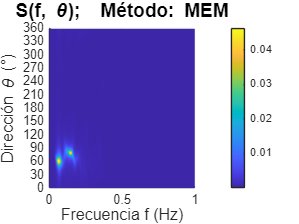

AST = data.burst_data.processed.ast(:, 1);
U = data.burst_data.processed.velocity_enu(:, 1);
V = data.burst_data.processed.velocity_enu(:, 2);

fs = data.burst_data.general.fs;
ast_mean = data.burst_data.general.ast_mean;
cell_position = data.burst_data.general.cell_position;
mounting_height = data.burst_data.general.mounting_height;

h   = ast_mean + mounting_height;
z_v = cell_position - ast_mean;

[out_DirSpec, info_DirSpec] = wsa_dirspectrum(AST, U, V, fs, 'SUV', ...
                                             'z_v', z_v, ...
                                             'h', h);

f = out_DirSpec.MEM.f;
theta = out_DirSpec.MEM.theta;
E = out_DirSpec.MEM.E;
S = out_DirSpec.MEM.S;
a1 = out_DirSpec.MEM.coeffs.a1;
b1 = out_DirSpec.MEM.coeffs.b1;
a2 = out_DirSpec.MEM.coeffs.a2;
b2 = out_DirSpec.MEM.coeffs.b2;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM';      %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)

## Bandas por defecto

### Utilizando vectores de frecuencia f, densidad espectral S y coeficientes direccionales a1, b1, a2 y b2.

En el struct de resultados se guardan los parametros correspondientes a la banda total del espectro direccional.

out_Dir_Params = wsa_directional_parameters(f, S, a1, b1, ...
                                            'a2', a2, ...
                                            'b2', b2)

out_Dir_Params = struct with fields:
                       fp: 0.0684
                       Tp: 14.6286
                    DirTp: 61.3594
                    SprTp: 28.3475
                  MeanDir: 69.1037
               MeanSpread: 40.2209
               f_mean_dir: [511×1 double]
                f_dir_spr: [511×1 double]
                       m0: 0.1144
                    a1_wa: 0.2688
                    b1_wa: 0.7040
                    R1_wa: 0.7536
              band_limits: [0.0020 0.9980]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0020 0.9980]
           source_spectra: [1×1 struct]


Los parámetros correspondientes a las bandas por defecto se pueden encontrar en el substruct *bands.*

ig = out_Dir_Params.bands.ig

ig = struct with fields:
              fp: 0.0332
              Tp: 30.1176
           DirTp: 71.8260
           SprTp: 67.9309
         MeanDir: 87.7754
      MeanSpread: 68.9792
      f_mean_dir: [16×1 double]
       f_dir_spr: [16×1 double]
              m0: 4.9335e-04
           a1_wa: 0.0107
           b1_wa: 0.2751
           R1_wa: 0.2753
     band_limits: [0.0033 0.0333]
    used_spectra: [1×1 struct]


swell1 = out_Dir_Params.bands.swell1

swell1 = struct with fields:
              fp: 0.0684
              Tp: 14.6286
           DirTp: 61.3594
           SprTp: 28.3475
         MeanDir: 62.7366
      MeanSpread: 29.7568
      f_mean_dir: [23×1 double]
       f_dir_spr: [23×1 double]
              m0: 0.0321
           a1_wa: 0.3963
           b1_wa: 0.7690
           R1_wa: 0.8651
     band_limits: [0.0333 0.0800]
    used_spectra: [1×1 struct]


swell2 = out_Dir_Params.bands.swell2

swell2 = struct with fields:
              fp: 0.0801
              Tp: 12.4878
           DirTp: 61.0882
           SprTp: 27.0912
         MeanDir: 71.7088
      MeanSpread: 29.4719
      f_mean_dir: [24×1 double]
       f_dir_spr: [24×1 double]
              m0: 0.0213
           a1_wa: 0.2723
           b1_wa: 0.8239
           R1_wa: 0.8677
     band_limits: [0.0800 0.1250]
    used_spectra: [1×1 struct]


swell = out_Dir_Params.bands.swell

swell = struct with fields:
              fp: 0.0684
              Tp: 14.6286
           DirTp: 61.3594
           SprTp: 28.3475
         MeanDir: 66.1429
      MeanSpread: 29.8522
      f_mean_dir: [47×1 double]
       f_dir_spr: [47×1 double]
              m0: 0.0551
           a1_wa: 0.3496
           b1_wa: 0.7904
           R1_wa: 0.8643
     band_limits: [0.0333 0.1250]
    used_spectra: [1×1 struct]


wind = out_Dir_Params.bands.wind

wind = struct with fields:
              fp: 0.1484
              Tp: 6.7368
           DirTp: 78.0560
           SprTp: 25.0972
         MeanDir: 72.4185
      MeanSpread: 44.3057
      f_mean_dir: [192×1 double]
       f_dir_spr: [192×1 double]
              m0: 0.0537
           a1_wa: 0.2118
           b1_wa: 0.6683
           R1_wa: 0.7010
     band_limits: [0.1250 0.5000]
    used_spectra: [1×1 struct]


### Utilizando el struct de salida de *wsa_dirspectrum*

También es posible pasar el struct de salida MEM o Fourier de wsa_dirspectrum a la función. En general, se puede emplear cualquier struct que contenga los campos f, S, coeffs.a1 y coeffs.b1, mientras sean consistentes en tamano.


out_Dir_Params = wsa_directional_parameters(out_DirSpec.MEM) %#ok<NASGU>

out_Dir_Params = struct with fields:
                       fp: 0.0684
                       Tp: 14.6286
                    DirTp: 61.3594
                    SprTp: 28.3475
                  MeanDir: 69.1037
               MeanSpread: 40.2209
               f_mean_dir: [511×1 double]
                f_dir_spr: [511×1 double]
                       m0: 0.1144
                    a1_wa: 0.2688
                    b1_wa: 0.7040
                    R1_wa: 0.7536
              band_limits: [0.0020 0.9980]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0020 0.9980]
           source_spectra: [1×1 struct]


## Bandas modificadas

### Modificando la banda total

Es posible modificar la banda frecuencial total, esto cambia el resultado del struct principal, pero no modifica el resto de bandas por defecto predefinidas.

out_Dir_Params = wsa_directional_parameters(out_DirSpec.MEM, 'TotalBand', [1/25 1/5]) %#ok<NASGU>

out_Dir_Params = struct with fields:
                       fp: 0.0684
                       Tp: 14.6286
                    DirTp: 61.3594
                    SprTp: 28.3475
                  MeanDir: 69.7661
               MeanSpread: 29.8097
               f_mean_dir: [82×1 double]
                f_dir_spr: [82×1 double]
                       m0: 0.0909
                    a1_wa: 0.2990
                    b1_wa: 0.8113
                    R1_wa: 0.8647
              band_limits: [0.0400 0.2000]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0400 0.2000]
           source_spectra: [1×1 struct]


### Redefiniendo bandas por defecto

Para redefinir las bandas por defecto, se debe crear un struct cuyos campos sean del tipo 'nombre', [fmin, fmax]. De esta forma puede verificarse en el substruct *band_definitions* los nuevos límites. Los parámetros en *bands* ahora corresponden a estos límites.

redefined_bands = struct('ig', [1/350, 1/25], ...
                         'wind', [1/8, 1/5]);
out_Dir_Params = wsa_directional_parameters(out_DirSpec.MEM, 'Bands', redefined_bands);
out_Dir_Params.band_definitions

ans = struct with fields:
        ig: [0.0029 0.0400]
    swell1: [0.0333 0.0800]
    swell2: [0.0800 0.1250]
     swell: [0.0333 0.1250]
      wind: [0.1250 0.2000]


### Agregando nuevas bandas

Para agregar bandas personalizadas, estas se definen mediante un struct cuyos campos sean del tipo 'nombre', [fmin fmax]. Estas bandas se agregan al substruct *bands*.

new_bands = struct('Banda1', [1/350, 1/25], ...
                   'wind2', [1/2, 1]);
out_Dir_Params = wsa_directional_parameters(out_DirSpec.MEM, 'CustomBands', new_bands);
out_Dir_Params.band_definitions

ans = struct with fields:
        ig: [0.0033 0.0333]
    swell1: [0.0333 0.0800]
    swell2: [0.0800 0.1250]
     swell: [0.0333 0.1250]
      wind: [0.1250 0.5000]
    Banda1: [0.0029 0.0400]
     wind2: [0.5000 1]



Banda1 = out_Dir_Params.bands.Banda1

Banda1 = struct with fields:
              fp: 0.0391
              Tp: 25.6000
           DirTp: 71.2565
           SprTp: 50.8259
         MeanDir: 79.1638
      MeanSpread: 65.0288
      f_mean_dir: [19×1 double]
       f_dir_spr: [19×1 double]
              m0: 8.1671e-04
           a1_wa: 0.0669
           b1_wa: 0.3496
           R1_wa: 0.3559
     band_limits: [0.0029 0.0400]
    used_spectra: [1×1 struct]


wind2 = out_Dir_Params.bands.wind2

wind2 = struct with fields:
              fp: 0.5020
              Tp: 1.9922
           DirTp: 151.3483
           SprTp: 77.5173
         MeanDir: 217.1600
      MeanSpread: 79.7554
      f_mean_dir: [255×1 double]
       f_dir_spr: [255×1 double]
              m0: 0.0038
           a1_wa: -0.0248
           b1_wa: -0.0188
           R1_wa: 0.0312
     band_limits: [0.5000 1]
    used_spectra: [1×1 struct]


### No incluir bandas por defecto

Es posible eliminar las bandas por defecto del cálculo.

out_Dir_Params = wsa_directional_parameters(out_DirSpec.MEM, 'IncludeDefaultBands', false)

out_Dir_Params = struct with fields:
                       fp: 0.0684
                       Tp: 14.6286
                    DirTp: 61.3594
                    SprTp: 28.3475
                  MeanDir: 69.1037
               MeanSpread: 40.2209
               f_mean_dir: [511×1 double]
                f_dir_spr: [511×1 double]
                       m0: 0.1144
                    a1_wa: 0.2688
                    b1_wa: 0.7040
                    R1_wa: 0.7536
              band_limits: [0.0020 0.9980]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0020 0.9980]
           source_spectra: [1×1 struct]


out_Dir_Params.band_definitions

ans = struct with no fields.
